# Lab 3: Modelling Action Potential Generation

**Author: **Tony Kabilan Okeke

warning('off', 'signal:findpeaks:largeMinPeakHeight')

**Objective:** This lab assignment will cover three models for action potential generation we’ve covered in class: the basic integrate-and-fire neuron (part I), the Hodgkin-Huxley model neuron (part II), and a Thalamic Relay model neuron (part III). In part I, you will investigate the behavior of one of the simplest models of action potential generation. In part II, you will test the Hodgkin-Huxley model by changing the input current and modifying the physical parameters of the cell. In part III, you will compare results obtained from the Hodgkin-Huxley model with those from a similar parallel conductance model that has an addition current pathway: a transient calcium conductance.

## Part I: Fun with the Integrate and Fire Neuron

In this section, you will be evaluating the leaky integrate-and-fire neuron. The model, originally proposed in 1907 by Louis Lapique, remains widely used in large-scale network simulations. The model relies on the passive membrane properties R and C to simulate the subthreshold behavior of a neuron. When a current is input, there is a transient RC response. Once the voltage response reaches a pre-defined threshold (VTh), the cell fires an action potential, at which point the voltage resets. Based on what we know, we can first analyze the circuit as a first order differential equation by substitution and rearrangement:

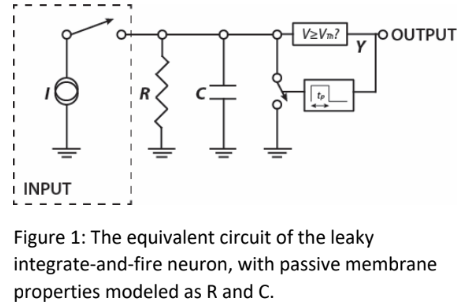 


$$~~~~~I_{in} = I_R + I_C \\
C\frac{dV}{dt} = -\frac{V}{R} + I_{in}$$


We will now use this model to understand its strengths and weaknesses. Open the Matlab m-file “intfire.m.” In this script, you can vary the input current (I), the membrane resistance (R), and the membrane capacitance (C), and plot the output voltage (V) as a function of time.

clear

#### A.  Vary the input current gradually from very low to high values and find the minimum current needed to cause the neuron to spike.

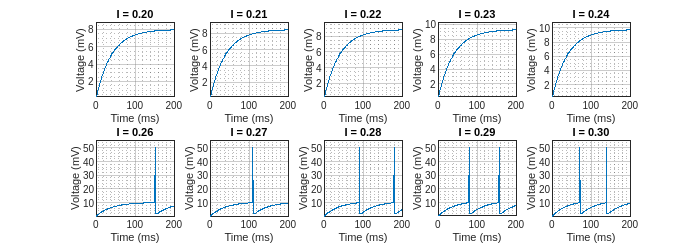

I_range = linspace(0.2, 0.3, 10);
figure('Color', 'w', 'Position', [100, 100, 700, 250]);

for i=1:numel(I_range)
    I = I_range(i);
    V_trace = intfire('I', I);

    subplot(2, 5, i);
    plot_intfire(V_trace); 
    title(sprintf('I = %.2f', I))
end

- We first observe spiking at $I=0.26~\mu A$

#### B.  Generate a graph showing input current (μA) versus the output firing rate (Hz = spikes/second) of the neuron. To calculate firing rate, count the number of spikes and divide this number by the simulation duration. Make sure to use multiple current values to capture the overall trend for the modeled data. What is the relationship between the current and firing rate?

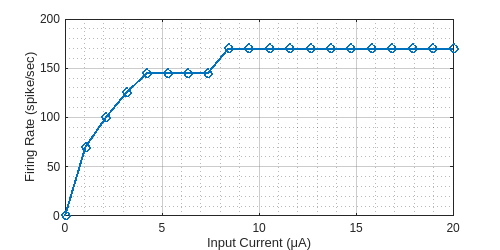

% Function for computing firing rate
firingrate = @(V_trace) sum(diff([0 V_trace > 45]) == 1) / size(V_trace, 2) * 1000;

% Iter
% I_range = 0.27:0.5:20; % skip 8 and 9
I_range = linspace(0, 20, 20);
FR = zeros(size(I_range));

for i = 1:numel(I_range)
    I = I_range(i);
    V_trace = intfire('I', I);

    FR(i) = firingrate(V_trace);
end

figure('Color', 'w', 'Position', [100, 100, 500, 250]);
plot(I_range, FR, 'o-', 'LineWidth', 1.5)
xlabel('Input Current (μA)'); ylabel('Firing Rate (spike/sec)')
grid on;
set(gca, 'GridAlpha', 0.4, 'MinorGridAlpha', 0.3, 'GridColor', [0.5 0.5 0.5]);
grid minor;

- The input current and firing rate appaer to have a roughly logarithmic relationship with firing rate rapidly increasing initially, and then slowly reaching a plateau at the maximum firing rate.

#### C.  What is the maximum firing rate of this neuron (provide example figure) and how is it related to the absolute refractory period (abs_ref) in the code?

% Max firing rate
fprintf('Max Firing Rate: %.2f spikes/sec', FR(end))

Max Firing Rate: 170.00 spikes/sec

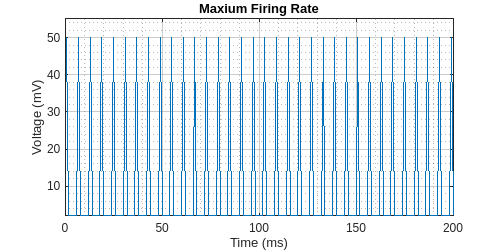

% Plot firing
figure('Color', 'w', 'Position', [100, 100, 500, 250]);
plot_intfire(V_trace); 
title('Maxium Firing Rate');

- For this simulation, the absolute refractory period is set to 5ms. This means that once a neuron fires a spike, it can not fire another one for 5ms. Therefore each action poetential takes about 6 ms to occur.

- Since the simulation runs for 200ms, the theoretical maximum number of spikes is 34 which is equivalent the the measured maximum firing rate of 170 spikes/sec.

#### D.  Instead of injecting a constant current, make the current (I) a sinusoidal function of time (e.g. I = sin((1:tstop)*f); I(I<0)=0;) where f is the input frequency (remember the default frequency in Matlab is radians). Plot a graph showing the output firing rate (Hz) as a function of input frequency (rad/ms). Vary f from 0.01 to 0.5 rad/ms.

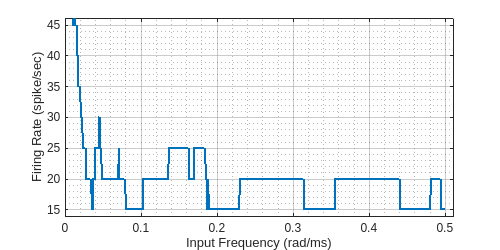

f_range = linspace(0.01, 0.5, 1000);
FR = zeros(size(f_range));

for i = 1:numel(f_range)
    f = f_range(i);
    V_trace = intfire('f', f, 'usesine', true);

    FR(i) = firingrate(V_trace);
end

figure('Color', 'w', 'Position', [100, 100, 500, 250]);
plot(f_range, FR, '-', 'LineWidth', 1.5)
xlabel('Input Frequency (rad/ms)'); ylabel('Firing Rate (spike/sec)')
xlim([0 0.51]); ylim([14 46])
grid on;
set(gca, 'GridAlpha', 0.4, 'MinorGridAlpha', 0.3, 'GridColor', [0.5 0.5 0.5]);
grid minor;

#### E.  Find the resonant frequencies (if any) where the neuron ‘tracks’ the input by firing exactly 1 spike for each peak in the input. Hint – replot the data from D. so that both axes are in Hz (spikes per second and cycles per second).

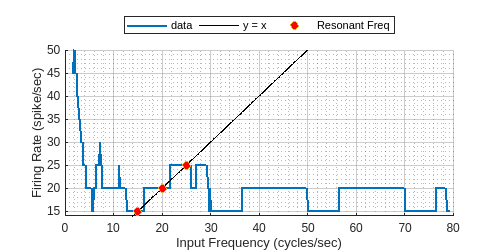

% Convert resonant frequencies to Hz
f_range_Hz = f_range * (1000 / (2 * pi));

% Plot
figure('Color', 'w', 'Position', [100, 100, 500, 250]); hold on
plot(f_range_Hz, FR, '-', 'LineWidth', 1.5, 'DisplayName', 'data')
plot(f_range_Hz, f_range_Hz, 'k', 'DisplayName', 'y = x')

% Find and plot resonant frequencies
threshold = 0.05; % Adjust this threshold as needed
resonant_indices = find(abs(FR - f_range_Hz) < threshold);
plot(f_range_Hz(resonant_indices), FR(resonant_indices), 'o', ...
     'Markerfacecolor', 'r', 'DisplayName', 'Resonant Freq');

xlabel('Input Frequency (cycles/sec)'); 
ylabel('Firing Rate (spike/sec)');
grid on;
set(gca, 'GridAlpha', 0.4, 'MinorGridAlpha', 0.3, 'GridColor', [0.5 0.5 0.5]);
grid minor;
hold off
legend('Orientation', 'horizontal', 'Location', 'northoutside')
xlim([0 80]); ylim([14 50])

fprintf(['Resonant requencies were:\n' sprintf('- %.2f Hz\n', f_range_Hz(resonant_indices))])

Resonant requencies were:
- 15.02 Hz
- 20.01 Hz
- 25.01 Hz


- The resonant frequencies are at points where the neuron fires a single spike for each peak in the input

- To identify these frequencies, the line $y = x$ was overlayed on the Firing Rate - Input Frequency plot. The intersections are the resonant frequencies (shown as red dots in the figure).

## Part II: Delving into the Hodgkin-Huxley Model

In this section, you will be simulating a variety of different input currents to characterize the behavior of the Hodgkin-Huxley model of action potential generation (Fig. 2). Recall that unlike the simplified RC model used above, Hodgkin and Huxley derived their model based on experimental observations of the squid giant axon. As such, the model attempts to explain action potential generation as a function of the time-varying ionic conductances gNa and gK, as well as the membrane capacitance, and a lumped gLeak that remains constant (the “leak” channels that are always open that contribute to the neuron’s resting membrane potential). Solving for the equivalent circuit, and based on the theorized dynamics of the ion channels, the full Hodgkin-Huxley model is composed of a set of four coupled ordinary differential equations that describe the membrane potential, along with the ionic conductance for potassium (n), and the fast activating (m) and slow inactivating (h) sodium channel subunits:

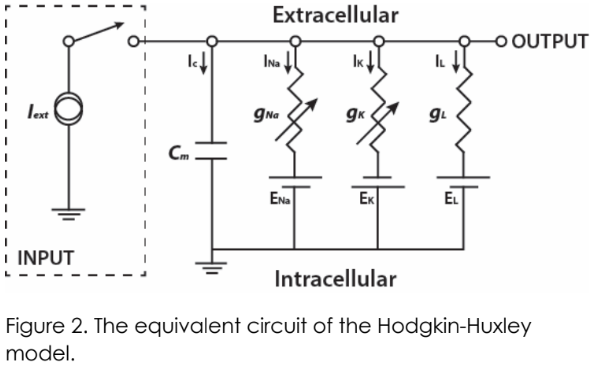

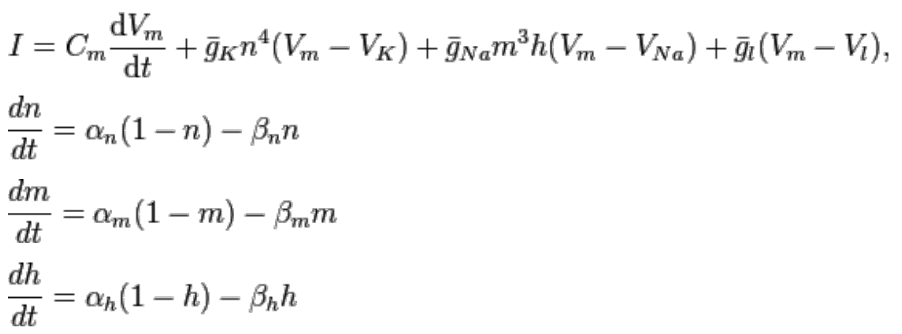

Now, open the Matlab m-files “HH_calc.m” and “HH.m.” The first m-file is the control script from which you will run the simulation. The second file is the Hodgkin-Huxley model that is executed via Matlab’s built-in ordinary differential equation solver ode45.

clear

#### A.  Run the simulation (via HH_calc.m) with the default parameter settings and aconstant current of 0.1 (currType=1;). Describe the resulting membrane potential in terms of the gating variables n, m, and h.

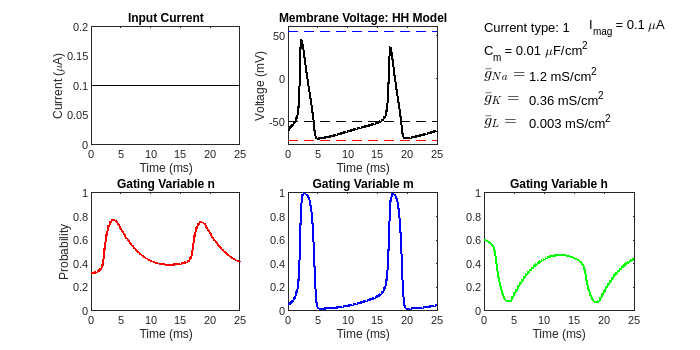

figure('Color', 'w', 'Position', [100, 100, 700, 350]);
runHH('plot', true);

- The initial depolarization corresponds with a rapid rise in the the gating variable 'm' and a decrease in the 'h' gating variable. This indicates that voltage-gated  sodium channels are likely to be open allowing sodium ions to flow into the cell.

- The repolarization phase of the action potential correlates with the increase in the gating variable 'n', indication that the voltage-gated potassium channels are open and potassium ions are flowing out of the cell.

#### B.  What is the minimum input current required to elicit an action potential (approximate to the nearest 0.01 μA)?

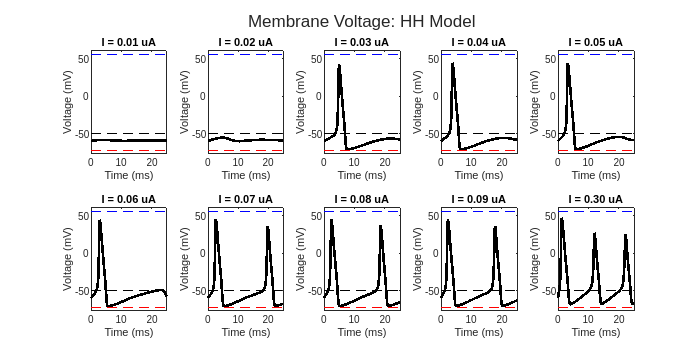

I_range = linspace(0.01, 0.1, 10);
I_range(end) = 0.3;

figure('Color', 'w', 'Position', [100, 100, 700, 350]);
tiledlayout(2, 5)
for i = 1:numel(I_range)
    Imag = I_range(i);
    res = runHH('Imag', Imag);

    nexttile
    plot(res.timeVect,res.OD,'k','linewidth',2);
    hold on
    plot([res.t(1) res.t(end)],[res.ENa res.ENa],'b--');
    plot([res.t(1) res.t(end)],[res.EK res.EK],'r--');
    plot([res.t(1) res.t(end)],[res.El res.El],'k--')
    xlabel('Time (ms)')
    ylabel('Voltage (mV)')
    title(sprintf('I = %.2f uA', Imag))
    axis tight
    set(gca,'ylim',[res.EK-5 res.ENa+5])
end
sgtitle('Membrane Voltage: HH Model');

- The minimum current required for an action potential is $0.03~\mu A$.

#### C.  Run a series of simulations using constant (currType=1) stimulation currents that range from the minimum current found in (B) to ten times that value. For each current, record the number of action potentials that are elicited (N), and measure the latencies of the first and last spikes in the train (t1 and tN). Calculate firing frequency in Hz (spikes per second) as (N-1)/(tN-t1). Plot the firing frequency as a function of stimulus current (μA) amplitude. What do you observe from the plot?

Note: firing frequency is 0 unless the cell fires repetitively during the stimulus current.

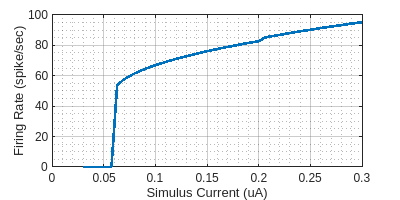

% Iter
I_range = linspace(0.03, 0.3, 50);
spikefreq = zeros(size(I_range));


for i = 1:numel(I_range)
    Imag = I_range(i);
    res = runHH('Imag', Imag);

    [~, locs] = findpeaks(res.OD, 'MinPeakHeight', 20);

    N = numel(locs);
    t = res.timeVect(locs);
    if N == 1
        spikefreq(i) = 0;
    else
        spikefreq(i) = (N - 1) / ((t(N) - t(1))) * 1000;
    end
end

figure('Color', 'w', 'Position', [100, 100, 400, 200]);
plot(I_range, spikefreq, 'LineWidth', 2)
xlabel('Simulus Current (uA)'); 
ylabel('Firing Rate (spike/sec)');
grid on;
set(gca, 'GridAlpha', 0.4, 'MinorGridAlpha', 0.3, 'GridColor', [0.5 0.5 0.5]);
grid minor;

- The firing rate reamins zero until the stimulus current exceeds $0.06~\mu A$(due to there only being one spike). We then observe a rapid increase in firing rate to around 53 spikes/sec, followed by a more gradual, continuous increase as the stimulus current is increased.

#### D.  Set Imag to 0.6 μA and give a concise qualitative description of what happens to spike amplitude during a spike train. Explain why this happens in terms of the gating variables m, n, and h.

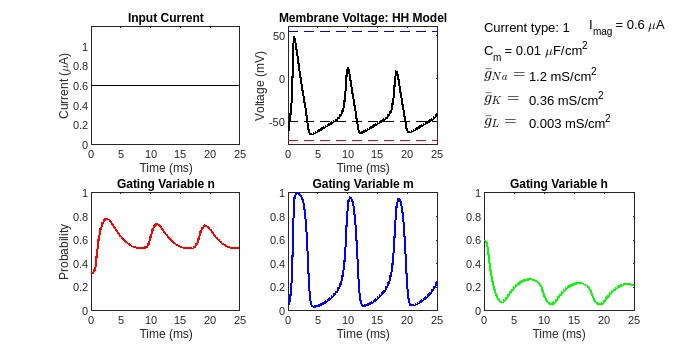

figure('Color', 'w', 'Position', [100, 100, 700, 350]);
res = runHH('Imag', 0.6, 'plot', true);

- We observe a decrease in the amplitude of spikes following the initial spike during a spike train. When the second spike starts, potasium channels are still open and some of the sodium channels are either already open or inactivated (reduced m and lower 'h'). This prevents the membrane potential from reaching the same peak as in the first spike. Effectively, membrane voltage of the neuron hasn't fully reset by the time the second spike begins, causing a diminished response.

#### E.  You have seen that depolarizing current can trigger action potentials. Can a hyperpolarizing step also trigger a spike? Set Imag to 0.1μA and currType to 4 (hyperpolarizing step input). Describe the output. How does this response differ from what would occur if the membrane were passive (linear)?

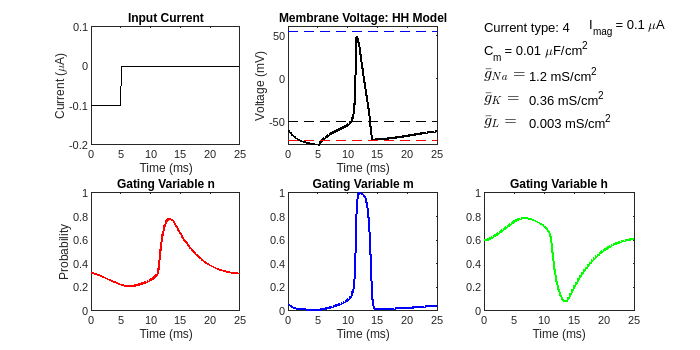

figure('Color', 'w', 'Position', [100, 100, 700, 350]);
runHH('Imag', 0.1, 'currType', 4, 'plot', true);

- The hyperpolarizing input current caused a rebound spike in the membrane potential.  If the membrane were entirely passive, the voltage would drop linearly in response to the hyperpolarizing current, with no influence from the gating variables.

#### F.  Increase the hyperpolarizing current (Imag) to 0.3 μA. Describe what occurs.

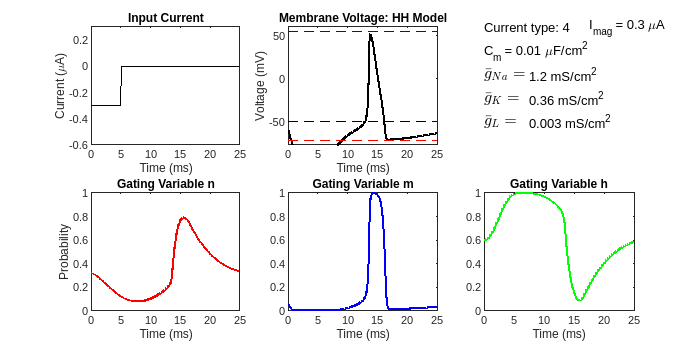

figure('Color', 'w', 'Position', [100, 100, 700, 350]);
runHH('Imag', 0.3, 'currType', 4, 'plot', true);

- We observe a more pronounced hyperpolarization prior to the action potential when the current is increased. 

#### G.  Does the rebound spike seem qualitatively similar to spikes triggered by depolarizing currents?

- Yes, the rebound spike appears similar to the spikes triggered by depolarizing currents. The differences between the two are primarily visible in the initial hyperpolarization.

#### H.  You decide to go to a fancy restaurant and order fugu. Unfortunately, your chef wasn’t very good and you received an unhealthy dose of tetrodotoxin (TTX). Simulate the effects of TTX on the HH model neuron. Describe what happens.

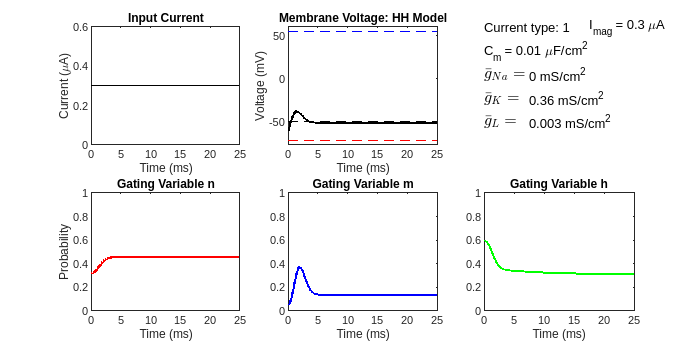

figure('Color', 'w', 'Position', [100, 100, 700, 350]);
runHH('Imag', 0.3, 'currType', 1, 'plot', true, 'TTX', true);

- TTX blocks voltage-gated sodium channels, effectively stopping the in flux of Na+ ions, thus inhibiting the initiation and propagation of action potentials. To replicate this in the simulations, I set `gbarNa = 0` 

- We observe a small depolarization at the beginning of the simulation, followed by the membrane potential returning to its baseline. Since the maxium conductance of sodium ions is set to zero, this drives the gating probabilites, m & h, towards zero as the simulation progresses.

- On the other hand, we see an increase in the gating probability, n which indicates that some potassium channels were opened in order to trigger the repolarisation of the cell (return to resting potential).

#### I.  Luckily you recovered from your TTX poisoning, but shortly after when working in the lab, you were exposed to tetraethylammonium (TEA). Simulate the effects of TEA on the HH model neuron. Why is this such a potent neurotoxin?

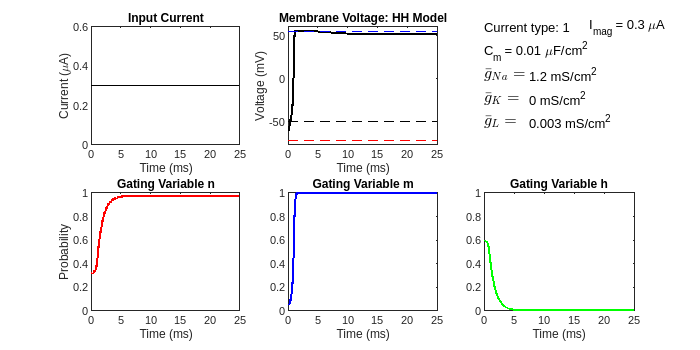

figure('Color', 'w', 'Position', [100, 100, 700, 350]);
runHH('Imag', 0.3, 'currType', 1, 'plot', true, 'TEA', true);

- TEA blocks voltage-gated potassium channels, stopping the efflux of potassium ions from the neuron during an action potential. To replicate this in the simulations, I set `gbarK = 0` 

- We see an initial depolarization, however since the potassium channels are blocked by TEA, the repolarization phase is impacted, resulting in the neuron remaining in a depolarized state.

- This effect makes TEA a very potent neurotoxin since it blocks the ability of neurons to communicate via action potentials . This would cause disruptions to rythmic activities in neural circuits, leading to potentially fatal conditions.

## Part III: The Thalmic Relay Neuron: Modelling the T-type Ca2+ Current

The Hodgkin-Huxley model we’ve investigated so far was generated from data collected during patch-clamp experiments on the squid giant axon. In the squid axon, Na+ and K+ currents are primarily responsible for the generation of an action potential. However, as we begin to investigate AP generation in other neuron types, it becomes necessary to modify our basic HH model to account for differences in neuron morphology. In this section, you will investigate the effects of a transient calcium current (T-type) on AP generation.

clear

#### A.  Run the simulation with default settings. Describe the output.

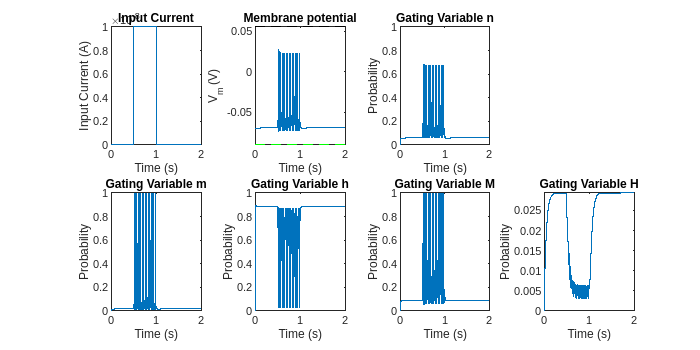

figure('Color', 'w', 'Position', [100, 100, 700, 350]);
runPIR('plot', true);

- We observe a burst of several action potentials, followed by the membrane returning to its resting potential.

#### B.  What is the minimum input current (Imag) that elicits only a single spike?

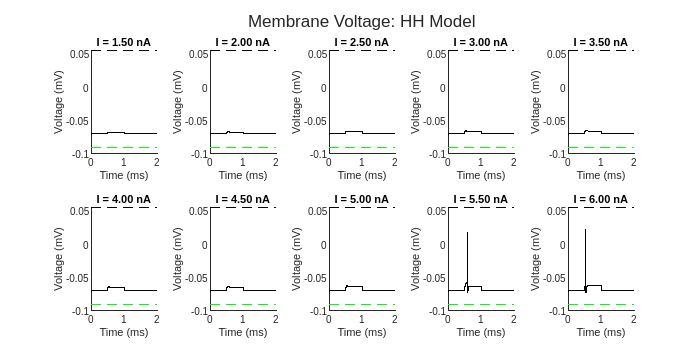

I_range = [1.5 2.0 2.5 3.0 3.5 4.0 4.5 5.0 5.5 6.0] * 10^-9;

figure('Color', 'w', 'Position', [100, 100, 700, 350]);
tiledlayout(2, 5)
for i = 1:numel(I_range)
    Imag = I_range(i);
    res = runPIR('Imag', Imag);

    nexttile; hold on
    plot(res.t, res.V, 'k')
    plot([0 res.tmax],[res.ENa res.ENa],'k--');
    plot([0 res.tmax],[res.EK  res.EK],'g--');
    xlabel('Time (ms)'); ylabel('Voltage (mV)')
    title(sprintf('I = %.2f nA', Imag/10^-9))
end
sgtitle('Membrane Voltage: HH Model');

- A minimum current of 5.5nA is required to trigger a single spike

#### C.  How is the depolarizing current related to the number of spikes in the burst? Vary the input current (Imag) while keeping the stimulation times fixed. Plot number of spikes in the burst as a function of input current.

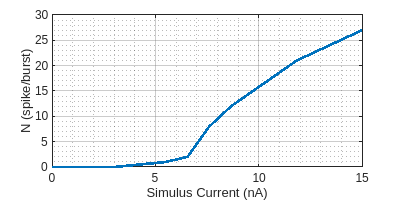

I_range = [0 3 linspace(5.5, 15, 10)] * 10^-9;
numspikes = zeros(size(I_range));

for i = 1: numel(I_range)
    Imag = I_range(i);
    res = runPIR('Imag', Imag);

    [pks, ~] = findpeaks(res.V, res.t, 'MinPeakHeight', 0.01);
    numspikes(i) = numel(pks);
end
figure('Color', 'w', 'Position', [100, 100, 400, 200]);
plot(I_range / 10^-9, numspikes, 'LineWidth', 2)
xlabel('Simulus Current (nA)'); 
ylabel('N (spike/burst)');
grid on;
set(gca, 'GridAlpha', 0.4, 'MinorGridAlpha', 0.3, 'GridColor', [0.5 0.5 0.5]);
grid minor;

- As the depolarizing current increases, so does the number of spikes.

### D.  Now, rather than a depolarizing current, provide a short hyperpolarizing (inhibitory) input (I0 =0, Imag = -5e-9 and Iend = 0) starting at t = 0.25 and lasting 0.25 s. Describe the output.

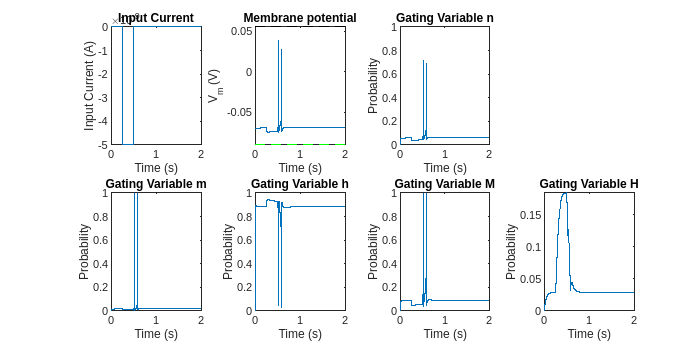

figure('Color', 'w', 'Position', [100, 100, 700, 350]);
res = runPIR('Imag', -5e-9, 'istart', 0.25, 'ilength', 0.25, 'plot', true);

- We see that the hyperpolarizing current caused the initiation of postinhibitory rebound spikes which occur as a result of calcium channels opening due to prolonged hyperpolarization.

#### E.  Is there an effect of further increasing the magnitude of the hyperpolarization on the number of spikes generated?

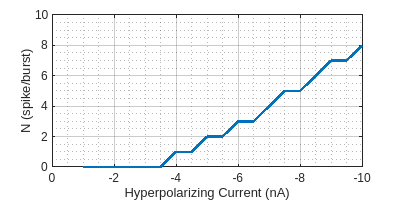

I_range = -(1:.5:10) * 10^-9;
numspikes = zeros(size(I_range));

figure;
for i = 1: numel(I_range)
    Imag = I_range(i);
    res = runPIR('Imag', Imag, 'istart', 0.25, 'ilength', 0.25);

    [pks, ~] = findpeaks(res.V, res.t, 'MinPeakHeight', 0.01);
    numspikes(i) = numel(pks);
end

figure('Color', 'w', 'Position', [100, 100, 400, 200]);
plot(I_range / 10^-9, numspikes, 'LineWidth', 2)
xlabel('Hyperpolarizing Current (nA)'); 
ylabel('N (spike/burst)');
grid on;
grid minor;
set(gca, 'GridAlpha', 0.4, 'MinorGridAlpha', 0.3, 'GridColor', [0.5 0.5 0.5], 'XDir', 'reverse');
ylim([0 10])

- We see that the number of spikes increases as the magnitude of the hyperpolarization increases. The number of spikes appears to plateau at around 7 spikes/burst at -20nA.

#### F.  Briefly explain why the added T-type Ca2+ current creates the bursting behavior.

- The T-type calcium channels have a low activation threshold and therefore require a less intense depolarization to open and allow the influx of calcium ions. This triggers a slight depolarization which is enough to trigger the opening of some sodium channels, thereby initiating an action potential.